# Sample script of negativeLayer

 Copyright (c) Shogo MURAMATSU, 2021

 All rights reserved.


type negativeLayer

classdef negativeLayer < nnet.layer.Layer
    % NEGATIVELAYER
    % 
    % Copyright (c) Shogo MURAMATSU, 2021
    % All rights reserved.
    % 
       
    methods
        function layer = negativeLayer(varargin) 
            p = inputParser;
            addParameter(p,'Name','')
            parse(p,varargin{:})
            
            % Set layer name.
            layer.Name = p.Results.Name;
            
            % Initialize scaling coefficient.        
            layer.NumInputs = 1;

            % Set layer description.
            layer.Description = "Negative";
        end
        
        function Z = predict(~, X)            
            Z = -X ;
        end
    end
end


layer = negativeLayer('Name','negative')

layer =   negativeLayer のプロパティ:

    Name: 'negative'

  すべてのプロパティを表示


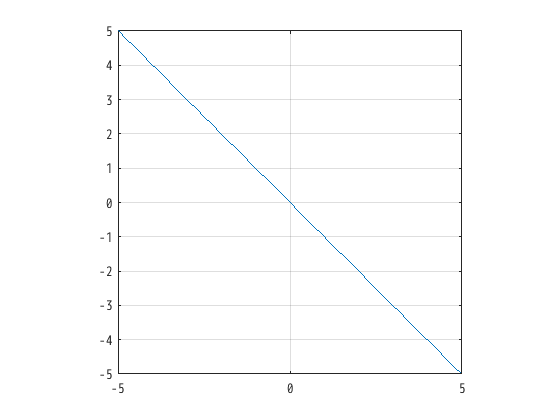


fplot(@(x) extractdata(layer.predict(dlarray(x))))
axis equal
grid on


checkLayer(layer,[24 24 20],'ObservationDimension',4)

GPU テストをスキップしています。互換性のある GPU デバイスが見つかりません。
 
コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... ...
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 13 パス、0 失敗、0 未完了、9 スキップ。
	 経過時間: 0.13806 秒。
